# Taller 2. Análisis Numérico y Computación Científica

Victor Manuel Sicacha y Juan Manuel Ramirez

1, Diferenciación numérica:

a. Haciendo uso de las fórmulas de tres y cinco puntos, encuentre el valor de la derivada de:

i. $y=tan\frac{x}{3}$ en 𝑥 = 3 con ℎ = 0.1 

syms x
f1a1(x) = tan(x/3)

$$f1a1(x) = \tan\left(\frac{x}{3}\right)$$

real(x) = diff(f1a1)

$$real(x) = \frac{{\tan\left(\frac{x}{3}\right)}^{2}}{3}+\frac{1}{3}$$

real = vpa(real(3))

$$real = 1.1418396069382532536472263111804$$

extrapolacion_richardson(f1a1,3,1,0.1,'3point-extremes')

$$ans = 1.1334269599408274860883859413641$$

extrapolacion_richardson(f1a1,3,1,0.1,'3point-middle')

$$ans = 1.1453517333306589309881266296979$$

extrapolacion_richardson(f1a1,3,1,0.1,'5point-extremes')

$$ans = 1.1412963501780569844477568619218$$

extrapolacion_richardson(f1a1,3,1,0.1,'5point-middle')

$$ans = 1.1417911815759782668783850137878$$

ii. $y = e^x + x$ en 𝑥 = 2 con ℎ = 0.2

f1a2(x) = exp(x)+x

$$f1a2(x) = x+{\mathrm{e}}^{x}$$

real(x) = diff(f1a2)

$$real(x) = {\mathrm{e}}^{x}+1$$

real = vpa(real(2))

$$real = 8.389056098930650227230427460575$$

extrapolacion_richardson(f1a2,2,1,0.2,'3point-extremes')

$$ans = 8.2742733007573284298947162904046$$

extrapolacion_richardson(f1a2,2,1,0.2,'3point-middle')

$$ans = 8.4384150875529371068518830346523$$

extrapolacion_richardson(f1a2,2,1,0.2,'5point-extremes')

$$ans = 8.3857350180040775245158096153378$$

extrapolacion_richardson(f1a2,2,1,0.2,'5point-middle')

$$ans = 8.3886601349678799555593217906849$$

b. Calcular la primera derivada de 𝑦 = cos 𝑥 en 𝑥 = 𝜋/4. Para ello emplee la extrapolación de Richardson con un paso $h_1 = \frac{\pi}{3}$ y $h_2 = \frac{\pi}{6}$ . Realice los cálculos haciendo uso de la fórmula de tres puntos de punto medio

f1b(x) = cos(x)

$$f1b(x) = \cos\left(x\right)$$

real(x) = diff(f1b)

$$real(x) = -\sin\left(x\right)$$

real = vpa(real(pi/4))

$$real = -0.70710678118654752440084436210485$$

extrapolacion_richardson(f1b,pi/4,2,pi/3,'3point-middle')

$$ans = -0.70539211584868712719300489232141$$

c.La distribución normal se define como: 


$$f(x)=\frac{1}{\sqrt{2\pi}}e^{-\frac{x^2}{2}}$$


Determine los puntos de inflexión de esta función.

f1c(x) = exp(-(x^2)/2)/sqrt(2*pi)

$$f1c(x) = \frac{2251799813685248\,{\mathrm{e}}^{-\frac{x^{2}}{2}}}{5644425081792261}$$

a1c = -4;
b1c = 0;
h1c = 0.1;
f1c2(x) = 1/h1c^2*(f1c(x-h1c)-2*f1c(x)+f1c(x+h1c))

$$f1c2(x) = \frac{225179981368524800\,{\mathrm{e}}^{-\frac{{\left(x-\frac{1}{10}\right)}^{2}}{2}}}{5644425081792261}-\frac{450359962737049600\,{\mathrm{e}}^{-\frac{x^{2}}{2}}}{5644425081792261}+\frac{225179981368524800\,{\mathrm{e}}^{-\frac{{\left(x+\frac{1}{10}\right)}^{2}}{2}}}{5644425081792261}$$


c1c = (a1c+b1c)/2;
e1c = abs(f1c2(c1c));

while e1c > 0.1/100
    if f1c2(a1c)*f1c2(b1c) < 0
        if f1c2(a1c)*f1c2(c1c) < 0
            b1c = c1c;
        elseif f1c2(b1c)*f1c2(c1c) < 0
            a1c = c1c;
        end
        c1c = vpa((a1c+b1c)/2);
        e1c = abs(f1c2(c1c));
    else
        break
    end
end
c1c

$$c1c = -1.0$$

vpa(f1c2(c1c))

$$ans = -0.00040221069813463925927551357036826$$


a1c = 0;
b1c = 4;
h1c = 0.1;

c1c = (a1c+b1c)/2;
e1c = abs(f1c2(c1c));

while e1c > 0.1/100
    if f1c2(a1c)*f1c2(b1c) < 0
        if f1c2(a1c)*f1c2(c1c) < 0
            b1c = c1c;
        elseif f1c2(b1c)*f1c2(c1c) < 0
            a1c = c1c;
        end
        c1c = vpa((a1c+b1c)/2);
        e1c = abs(f1c2(c1c));
    else
        break
    end
end
c1c

$$c1c = 1.0$$

vpa(f1c2(c1c))

$$ans = -0.00040221069813463925927551357036826$$

Puntos de inflexion en x=-1 y x=1

2. Integración numérica:

a. Evalúe la siguiente integral:


$$\int_0^{\frac{\pi}{2}}(6+3cosx)dx$$


i. En forma analítica.


$$\int_0^{\frac{\pi}{2}}(6+3cosx)dx  =  (6x+3sinx)|_0^{\frac{\pi}{2}} =  3\pi+3$$


real2 = 3*pi+3

real2 =           12.4247779607694


f2a(x) = 6+3*cos(x)

$$f2a(x) = 3\,\cos\left(x\right)+6$$

ii. Con una sola aplicación de la regla del trapecio.

trapecio2 = integracion_numerica(f2a, 0, pi/2, 'cerrado', 'trapecio', 1)

$$trapecio2 = 11.780972450961724644234912687298$$

iii. Con aplicación múltiple de la regla del trapecio (n=2 y n=4).

trapecio2_2 = integracion_numerica(f2a, 0, pi/2, 'cerrado', 'trapecio', 2)

$$trapecio2\_2 = 12.268956307674939522442376789841$$

trapecio2_4 = integracion_numerica(f2a, 0, pi/2, 'cerrado', 'trapecio', 4)

$$trapecio2\_4 = 12.386125363687705952222355141149$$

iv. Con una sola aplicación de la regla de Simpson 1/3.

simpson132 = integracion_numerica(f2a, 0, pi/2, 'cerrado', 'simpson13', 2)

$$simpson132 = 12.431617593246011148511531490689$$

v. Con aplicación múltiple de la regla de Simpson 1/3 (n=4)

simpson132_4 = integracion_numerica(f2a, 0, pi/2, 'cerrado', 'simpson13', 4)

$$simpson132\_4 = 12.425181715691961428815681258252$$

vi. Con una sola aplicación de la regla de Simpson 3/8

simpson382 = integracion_numerica(f2a, 0, pi/2, 'cerrado', 'simpson38', 3)

$$simpson382 = 12.427792730712216607356047765636$$

vii. Con aplicación múltiple de la regla de Simpson 3/8 (n=6)

simpson382_6 = integracion_numerica(f2a, 0, pi/2, 'cerrado', 'simpson38', 6)

$$simpson382\_6 = 12.424957040392217827645008479028$$

viii. Encontrar el error relativo porcentual para cada caso

error_trapecio2 = abs(trapecio2 - real2)/real2 * 100

$$error\_trapecio2 = 5.181625875652979028217548234296$$

error_trapecio2_2 = abs(trapecio2_2 - real2)/real2 * 100

$$error\_trapecio2\_2 = 1.2541202232059113880144740366485$$

error_trapecio2_4 = abs(trapecio2_4 - real2)/real2 * 100

$$error\_trapecio2\_4 = 0.31109285979771272753729012871078$$


error_simpson132 = abs(simpson132 - real2)/real2 * 100

$$error\_simpson132 = 0.055048327609777825386550695900654$$

error_simpson132_4 = abs(simpson132_4 - real2)/real2 * 100

$$error\_simpson132\_4 = 0.0032495946716868259551045072684698$$


error_simpson382 = abs(simpson382 - real2)/real2 * 100

$$error\_simpson382 = 0.024264175604234104205250610652901$$

error_simpson382_6 = abs(simpson382_6 - real2)/real2 * 100

$$error\_simpson382\_6 = 0.0014413104475904091423605165345321$$

b. La cantidad de masa (𝑚𝑔) transportada por un tubo durante un período de tiempo que va de $t_1$(𝑚𝑖𝑛) (tiempo inicial) a $t_2$(𝑚𝑖𝑛) (tiempo final), se calcula con:


$$\int_{t_1}^{t_2}Q(t)c(t)dt$$


Donde $Q(t)(\frac{m^3}{min})$ es la tasa de flujo y $c(t)(\frac{mg}{m^3})$ es la concentración. La tasa de flujo y la concentración se encuentran definidas como se muestran a continuación:


$$Q(t) = 9 + 5 cos^2(0.4)t$$



$$c(t)=5e^{-0.5t}+2e^{0.15t}$$


Determine la masa transportada entre un tiempo inicial de 2 minutos y un tiempo final de 8 minutos, con integración de Romberg para una tolerancia de 0.1%. 

q2b(x) = 9 + 5*(cos(0.4))^2*x

$$q2b(x) = 5\,{\cos\left(\frac{2\,x}{5}\right)}^{2}+9$$

c2b(x) = 5*exp(-0.5*x)+2*exp(0.15*x)

$$c2b(x) = 5\,{\mathrm{e}}^{-\frac{x}{2}}+2\,{\mathrm{e}}^{\frac{3\,x}{20}}$$

f2b(x) = q2b(x)*c2b(x)

$$f2b(x) = \left(5\,{\cos\left(\frac{2\,x}{5}\right)}^{2}+9\right)\,\left(5\,{\mathrm{e}}^{-\frac{x}{2}}+2\,{\mathrm{e}}^{\frac{3\,x}{20}}\right)$$


a2b = 2;
b2b = 8;
n2b = 1;
%h2b = (b2b-a2b)/n2b;
%while h2b^(2*n2b) > 0.1/100
%    n2b = n2b +1;
%    h2b = (b2b-a2b)/n2b;
%end
R2b = romberg(f2b, a2b, b2b, n2b, n2b);
R2bn = romberg(f2b, a2b, b2b, n2b+1, n2b+1);
while abs(R2bn - R2b) > 0.1/100
    n2b = n2b + 1;
    R2b = R2bn;
    R2bn = romberg(f2b, a2b, b2b, n2b+1, n2b+1);
end
n2b

n2b =      5


R2b

$$R2b = 335.96253871674692066213216254175$$

Masa transportada alrededor de $335.96253871674692066213216254175$ mg

Empleando la ecuación de caída libre de un paracaidista, definida como:


$$v(t) = \frac{gm}{c}(1-e^{-\frac{c}{m}t})$$


Donde 𝑣(𝑡) es la velocidad $(\frac{m}{s})$, 𝑡 es el tiempo (𝑠), 𝑔 es la gravedad $(\frac{9.81m}{s^2})$, 𝑚 es la masa (𝑘𝑔), y 𝑐 es el coeficiente de arrastre lineal $(\frac{kg}{s})$. Use la integración de Romberg para la calcular la distancia que a la que viaja un paracaidista de 80𝐾𝑔, durante los primeros 8 segundos, teniendo en cuenta un coeficiente de arrastre de 10𝐾𝑔/𝑠. Calcule la respuesta con un error relativo de 1%.

g2c = 9.81;
m2c = 80;
c2c = 10;
v2c(x) = g2c*m2c/c2c*(1-exp(-c2c/m2c*x))

$$v2c(x) = \frac{1962}{25}-\frac{1962\,{\mathrm{e}}^{-\frac{x}{8}}}{25}$$


a2c = 0;
b2c = 8;
n2c = 1;
%h2c = (b2c-a2c)/n2c;
%while h2c^(2*n2c) > 1/100
%    n2c = n2c +1;
%    h2c = (b2c-a2c)/n2c;
%end
R2c = romberg(v2c, a2c, b2c, n2c, n2c);
R2cn = romberg(v2c, a2c, b2c, n2c+1, n2c+1);
while abs(R2cn - R2c) > 1/100
    n2c = n2c + 1;
    R2c = R2cn;
    R2cn = romberg(v2c, a2c, b2c, n2c+1, n2c+1);
end
n2c

n2c =      3


R2c

$$R2c = 230.96922983477411274317985988402$$

Se desplaza al rededor de $230.96922983477411274317985988402$ metros

3. Problemas de valores iniciales:

syms t
syms y

a. La siguiente ecuación describe el flujo de agua en un tanque cilíndrico vertical cuando se abre una válvula en la base para drenarlo:


$$\frac{dy}{dt} = -k\sqrt{y}$$


𝑘 es una constante que depende de la forma del agujero y del área de la sección transversal del tanque y del agujero de drenaje. La profundidad del agua 𝑦 se mide en metros y el tiempo 𝑡 en minutos. Asumiendo un 𝑘 = 0.06, calcule el tiempo que se requiere para vaciar el tanque si el nivel del fluido se encuentra inicialmente en 3m. Resuelva con el método de RK4 usando un paso de 0.25 minutos

f3a(t,y) = -0.06*sqrt(y) 

$$f3a(t, y) = -\frac{3\,\sqrt{y}}{50}$$

[w,tv] = taylor_2v_step(f3a, 0, 0.25, 3, 'RK4', 0)

w =                           3 +                     0i           2.97407548788671 +                     0i           2.94826347577342 +                     0i           2.92256396366013 +                     0i           2.89697695154684 +                     0i           2.87150243943355 +                     0i           2.84614042732027 +                     0i           2.82089091520699 +                     0i           2.79575390309371 +                     0i           2.77072939098044 +                     0i           2.74581737886717 +                     0i            2.7210178667539 +                     0i           2.69633085464063 +                     0i           2.67175634252736 +                     0i            2.6472943304141 +                     0i           2.62294481830084 +                     0i           2.59870780618758 +                     0i           2.57458329407433 +                     0i           2.55057128196108 +                     0i        

tv =                          0                      0.25                       0.5                      0.75                         1                      1.25                       1.5                      1.75                         2                      2.25                       2.5                      2.75                         3                      3.25                       3.5                      3.75                         4                      4.25                       4.5                      4.75                         5                      5.25                       5.5                      5.75                         6                      6.25                       6.5                      6.75                         7                      7.25                       7.5                      7.75                         8                      8.25                       8.5                      8.75                         9                      9.25       

tv(end)

ans =                      57.75


El tanque se drena en aproximadamente 57.75 minutos

b. Encuentre la solución del siguiente problema de valor inicial teniendo en cuenta que 0 ≤ 𝑥 ≤ 1, ℎ = 0.05 y 𝑦(0) = 1. Grafique todos los resultados en una misma figura


$$\frac{dy}{dx}=(1+4x)*\sqrt{y}$$


i. Analíticamente. 


$$\int\frac{dy}{\sqrt{y}}=\int(1+4x)dx$$



$$2\sqrt{y}=(x+2x^2+c)$$



$$y=(\frac{x}{2}+x^2+c)^2$$


Dado y(0)=1:


$$1=c
$$



$$y=(\frac{x}{2}+x^2+1
)^2$$


f3b(t,y) = (1+4*t)*sqrt(y)

$$f3b(t, y) = \sqrt{y}\,\left(4\,t+1\right)$$

real3b1(t) = (t/2+t^2+1)^2 

$$real3b1(t) = {\left(t^{2}+\frac{t}{2}+1\right)}^{2}$$

fplot(real3b1)
xlim([0 1])
hold on 

ii. Método de Euler. 

[w3b2,tv3b2] = taylor_2v(f3b, 0, 1, 1, 1/0.05, 'euler')

w3b2 =                          1                      1.05          1.11148170459576          1.18528048746187          1.27237695765301          1.37389667670792          1.49111001539887          1.62543213266303          1.77842305628384          1.95178784409035          2.14737680529259          2.36718576352469          2.61335634573596           2.8881762838623          3.19407971894785          3.53364749989006          3.90960747115775          4.32483474564494          4.78235196028196          5.28532951315973          5.83708578177659


tv3b2 =                          0                      0.05                       0.1                      0.15                       0.2                      0.25                       0.3                      0.35                       0.4                      0.45                       0.5                      0.55                       0.6                      0.65                       0.7                      0.75                       0.8                      0.85                       0.9                      0.95                         1


plot(tv3b2,w3b2)

iii. Método de Punto Medio. 

[w3b3,tv3b3] = taylor_2v(f3b, 0, 1, 1, 1/0.05, 'punto medio')

w3b3 =                          1          1.05568325601112           1.1234364321683          1.20423248554081          1.29919416813632          1.40959406656465          1.53685463964262          1.68254825299367          1.84839721004975          2.03627377916948           2.2482002168326          2.48634878705375          2.75304177728248          3.05075151113095          3.38210035830534          3.74986074212246          4.15695514497818          4.60645611210675          5.10158625393559          5.64571824730286          6.24237483576818


tv3b3 =                          0                      0.05                       0.1                      0.15                       0.2                      0.25                       0.3                      0.35                       0.4                      0.45                       0.5                      0.55                       0.6                      0.65                       0.7                      0.75                       0.8                      0.85                       0.9                      0.95                         1


plot(tv3b3,w3b3)

iv. Método de Euler Modificado. 

[w3b4,tv3b4] = taylor_2v(f3b, 0, 1, 1, 1/0.05, 'euler modificado')

w3b4 =                          1          1.05574085229788          1.12356296854379          1.20443927795376          1.29949252547593          1.40999530864479          1.53737011184606          1.68318933743815           1.8491753334365          2.03720041767246          2.24928689849246          2.48760709217343            2.754483337303          3.05238800641612          3.38394351519894          3.75192232957201          4.15924697095378          4.60899001998517          5.10437411897062          5.64877197326358          6.24570635179576


tv3b4 =                          0                      0.05                       0.1                      0.15                       0.2                      0.25                       0.3                      0.35                       0.4                      0.45                       0.5                      0.55                       0.6                      0.65                       0.7                      0.75                       0.8                      0.85                       0.9                      0.95                         1


plot(tv3b4,w3b4)

v. Método de Runge-Kutta de cuarto orden. 

[w3b5,tv3b5] = taylor_2v(f3b, 0, 1, 1, 1/0.05, 'RK4')

w3b5 =                          1          1.05575623497281          1.12359996652391          1.20450619411285          1.29959991705028          1.41015613452073          1.53759984561703           1.6835060493805          1.84959974484128          2.03775593105476          2.24999960713115           2.4885057722572          2.75559942571003           3.0537555668639          3.38559919519119          3.75390531025903          4.16159891172286          4.61175499931815          5.10759857285115          5.65250463218942          6.24999817725263


tv3b5 =                          0                      0.05                       0.1                      0.15                       0.2                      0.25                       0.3                      0.35                       0.4                      0.45                       0.5                      0.55                       0.6                      0.65                       0.7                      0.75                       0.8                      0.85                       0.9                      0.95                         1


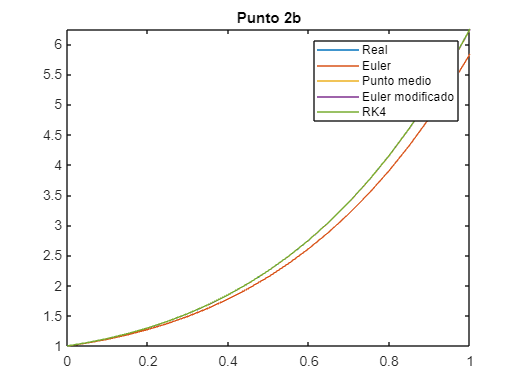

plot(tv3b5,w3b5)
hold off
title('Punto 2b')
legend('Real', 'Euler', 'Punto medio', 'Euler modificado', 'RK4')

c. El movimiento de un sistema de masa resorte como el mostrado en la figura, se encuentra definido por la siguiente ecuación diferencial ordinaria:


$$m \frac{d^2x}{dt^2}+ c\frac{dx}{dt}+kx=0$$


Donde 𝑥 corresponde al desplazamiento desde la posición de equilibrio en metros, 𝑡 es el tiempo en segundos, 𝑚 es la masa en kilogramos, 𝑘 es la constante del resorte en 𝑁/𝑚 y 𝑐 es el coeficiente de amortiguamiento en 𝑁 ∙ 𝑚/𝑠. Resuelva la ecuación asumiendo que 𝑚 = 20 𝑘𝑔, 𝑘 = 20 𝑁/𝑚, 𝑥(0) = 1, la velocidad inicial es cero,el intervalo de tiempo es 0 ≤ 𝑡 ≤ 15 y la constante de amortiguamiento tomará los valores de 5, 40 y 200 para que el sistema se comporte de forma subamortiguada, amortiguada críticamente y sobreamortiguada, respectivamente. Grafique el 𝑥 vs. 𝑡 para los tres casos. 

syms v
m3c = 20;
k3c = 20;
x3c0 = 1;
v3c0 = 0;
a3c = 0;
b3c = 15;

c3c1 = 5;
c3c2 = 40;
c3c3 = 200;

v3c(t,y,v) = v

$$v3c(t, y, v) = v$$

f3c1(t,y,v) = -(c3c1*v+k3c*y)/m3c

$$f3c1(t, y, v) = -\frac{v}{4}-y$$

[w3c1,tv3c1] = taylor_2v2y(v3c, f3c1, a3c, b3c, x3c0, v3c0, 100, 'RK4')

w3c1 =                          1         0.988910400390625         0.956431581527804         0.904066665170977         0.833701776219723         0.747550372688256         0.648092409601217         0.538009867885854         0.420120203106552         0.297309257511991          0.17246513388741        0.0484144533524878       -0.0721376856429241        -0.186662859935572        -0.292858550131771        -0.388690577909558        -0.472428066694507         -0.54267043028991        -0.598366087994156        -0.638822798196852        -0.663709691164315         -0.67305126171941        -0.667213750143872        -0.646884491644022        -0.613044948346862        -0.566938250764479        -0.510032166250439        -0.443978478999822        -0.370569809004134        -0.291694916008598        -0.209293529412807        -0.125311717192985       -0.0416587577567564        0.0398335899627411          0.11744860867987         0.189618228200703          0.25495211756888          0.31226178878154     

tv3c1 =                          0                      0.15                       0.3                      0.45                       0.6                      0.75                       0.9                      1.05                       1.2                      1.35                       1.5                      1.65                       1.8                      1.95                       2.1                      2.25                       2.4                      2.55                       2.7                      2.85                         3                      3.15                       3.3                      3.45                       3.6                      3.75                       3.9                      4.05                       4.2                      4.35                       4.5                      4.65                       4.8                      4.95                       5.1                      5.25                       5.4                      5.55    

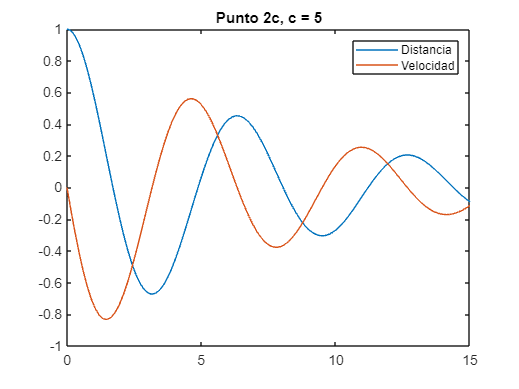

plot(tv3c1,w3c1)
title('Punto 2c, c = 5')
legend('Distancia', 'Velocidad')


f3c2(t,y,v) = -(c3c2*v+k3c*y)/m3c

$$f3c2(t, y, v) = -2\,v-y$$

[w3c2,tv3c2] = taylor_2v2y(v3c, f3c2, a3c, b3c, x3c0, v3c0, 100, 'RK4')

w3c2 =                          1             0.98981171875         0.963059621690063         0.924555777223666          0.87809306694657         0.826635749361758         0.772476710178831         0.717366982407409         0.662622210417936         0.609209968023007          0.55782119869414         0.508928507060357         0.462833578605536         0.419705625284266          0.37961243703954          0.34254535316543         0.308439244876913         0.277188414382005         0.248659160344752          0.22269962994996         0.199147469679471           0.1778356968904         0.158597139408247         0.141267728140389         0.125688876101356         0.111709134476266        0.0991852809690779        0.0879829664602614        0.0779770219050432        0.0690515075768585        0.0610995704797314        0.0540231624149996        0.0477326602881851        0.0421464213603242        0.0371902989339534        0.0327971381250327        0.0289062666652294        0.0254629919020992     

tv3c2 =                          0                      0.15                       0.3                      0.45                       0.6                      0.75                       0.9                      1.05                       1.2                      1.35                       1.5                      1.65                       1.8                      1.95                       2.1                      2.25                       2.4                      2.55                       2.7                      2.85                         3                      3.15                       3.3                      3.45                       3.6                      3.75                       3.9                      4.05                       4.2                      4.35                       4.5                      4.65                       4.8                      4.95                       5.1                      5.25                       5.4                      5.55    

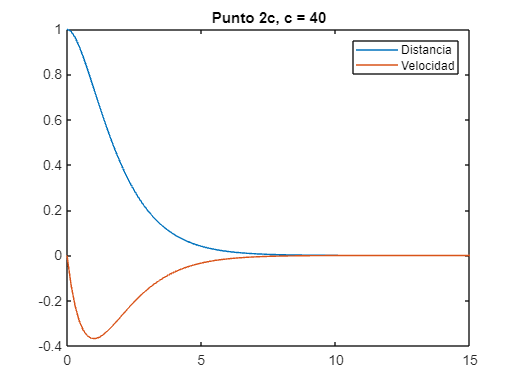

plot(tv3c2,w3c2)
title('Punto 2c, c = 40')
legend('Distancia', 'Velocidad')


f3c3(t,y,v) = -(c3c3*v+k3c*y)/m3c

$$f3c3(t, y, v) = -10\,v-y$$

[w3c3,tv3c3] = taylor_2v2y(v3c, f3c3, a3c, b3c, x3c0, v3c0, 100, 'RK4')

w3c3 =                          1             0.99228671875         0.979374416338501          0.96519756074989         0.950833548914895         0.936575674090691         0.922502063715482         0.908631827292045         0.894967911580929         0.881508861939179         0.868252049771006         0.855194557809185         0.842333422581675         0.829665700461421         0.817188485304962         0.804898912811655         0.792794161245536         0.780871451166025          0.76912804489362         0.757561245909798         0.746168398245666         0.734946885874244         0.723894132110363         0.713007599019168         0.702284786833403         0.691723233379422         0.681320513511833         0.671074238556634         0.660982055762723         0.651041647761665         0.641250732035572         0.631607060392996         0.622108418452693         0.612752625135162         0.603537532161822         0.594461023561725         0.585521015185686         0.576715454227721     

tv3c3 =                          0                      0.15                       0.3                      0.45                       0.6                      0.75                       0.9                      1.05                       1.2                      1.35                       1.5                      1.65                       1.8                      1.95                       2.1                      2.25                       2.4                      2.55                       2.7                      2.85                         3                      3.15                       3.3                      3.45                       3.6                      3.75                       3.9                      4.05                       4.2                      4.35                       4.5                      4.65                       4.8                      4.95                       5.1                      5.25                       5.4                      5.55    

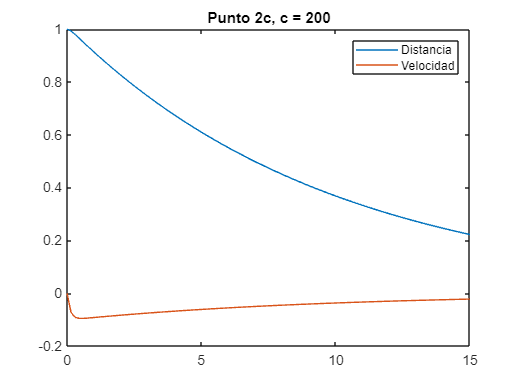

plot(tv3c3,w3c3)
title('Punto 2c, c = 200')
legend('Distancia', 'Velocidad')

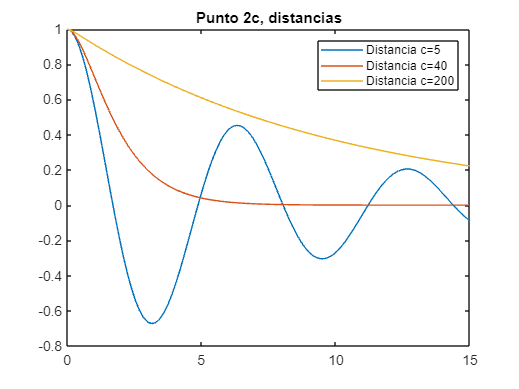


plot(tv3c1,w3c1(1,:))
hold on
plot(tv3c1,w3c2(1,:))
plot(tv3c1,w3c3(1,:))
hold off
title('Punto 2c, distancias')
legend('Distancia c=5', 'Distancia c=40', 'Distancia c=200')

d. Una población puede simularse mediante el siguiente modelo logístico:


$$\frac{dp}{dt}=k(1-\frac{p}{*p_{max}})p$$


donde 𝑝 es la población en millones de personas, 𝑘 es la tasa de crecimiento en condiciones ilimitadas (0.026/𝑎ñ𝑜) y 𝑝𝑚á𝑥 es la capacidad de carga (12000 millones de personas). Simule la población mundial entre 1950 y 2000 usando como condiciones iniciales:

t3d = [1950 1960 1970 1980 1990 2000]

t3d =         1950        1960        1970        1980        1990        2000


p3d = [2555 3040 3708 4454 5276 6079]

p3d =         2555        3040        3708        4454        5276        6079


k3d = 0.026;
pmax = 12000;
f3d(t,y) = k3d*(1-y/pmax)*y

$$f3d(t, y) = -y\,\left(\frac{13\,y}{6000000}-\frac{13}{500}\right)$$

i. Por el método de Euler.

[w11,tv11] = taylor_2v(f3d, t3d(1), t3d(2), p3d(1), 100, 'euler');
[w12,tv12] = taylor_2v(f3d, t3d(2), t3d(3), p3d(2), 100, 'euler');
[w13,tv13] = taylor_2v(f3d, t3d(3), t3d(4), p3d(3), 100, 'euler');
[w14,tv14] = taylor_2v(f3d, t3d(4), t3d(5), p3d(4), 100, 'euler');
[w15,tv15] = taylor_2v(f3d, t3d(5), t3d(6), p3d(5), 100, 'euler');

tv1 = [tv11 tv12 tv13 tv14 tv15];
w1 = [w11 w12 w13 w14 w15];

ii. Por el método de RK4. 

[w21,tv21] = taylor_2v(f3d, t3d(1), t3d(2), p3d(1), 100, 'RK4');
[w22,tv22] = taylor_2v(f3d, t3d(2), t3d(3), p3d(2), 100, 'RK4');
[w23,tv23] = taylor_2v(f3d, t3d(3), t3d(4), p3d(3), 100, 'RK4');
[w24,tv24] = taylor_2v(f3d, t3d(4), t3d(5), p3d(4), 100, 'RK4');
[w25,tv25] = taylor_2v(f3d, t3d(5), t3d(6), p3d(5), 100, 'RK4');

tv2 = [tv21 tv22 tv23 tv24 tv25];
w2 = [w21 w22 w23 w24 w25];

iii. Por algún método de interpolación. 

p3d3 = splines(t3d, p3d)

p3d3 =                       2555
          44.0019138755981
      1.99840144432528e-15
        0.0449808612440192
                      3040
          57.4961722488039
          1.34942583732058
       -0.0419043062200964
                      3708
          71.9133971291866


iv. Grafique las tres aproximaciones en una misma figura y discuta su resultado.

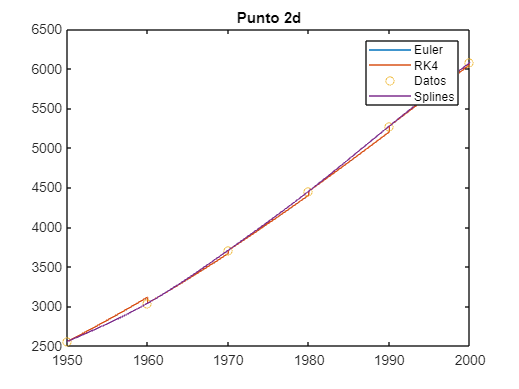

plot(tv1, w1)
hold on
plot(tv2, w2)

scatter(t3d,p3d)
range1 = t3d(1):.01:t3d(2);
range2 = t3d(2):.01:t3d(3);
range3 = t3d(3):.01:t3d(4);
range4 = t3d(4):.01:t3d(5);
range5 = t3d(5):.01:t3d(6);

plot([range1 range2 range3 range4 range5], [polyval(flip(p3d3(1:4)), range1-t3d(1)) polyval(flip(p3d3(5:8)), range2-t3d(2)) polyval(flip(p3d3(9:12)), range3-t3d(3)) polyval(flip(p3d3(13:16)), range4-t3d(4)) polyval(flip(p3d3(17:20)), range5-t3d(5))])

hold off
title('Punto 2d')
legend('Euler', 'RK4', 'Datos', 'Splines')

Se puede ver que el uso de metodos de interpolacion tiene un comportamiento mas suave y continuo dando una mejor aproximacion para una tendencia general. Sin embargo, la interpolacion requiere conocer el dato findal, mientras que euler y RK4 permiten aproximar los valores solo conociendo el comportamiento y el valor inicial teniendo un error aceptable para tiempos iniciales pero incrementando haciendo los valores finales lejanos al real.

e. Emplee el método de Runge – Kutta Fehlberg para dar solución a las siguientes ecuaciones: 

i. $y' = 4e^{0.8x}-0.5y$

con $0 \leq x \leq2$

h = 0.2

y(0) = 2


$$\epsilon = 10^{-5}$$


f3e1(t,y) = 4*exp(0.8*t)-0.5*y

$$f3e1(t, y) = 4\,{\mathrm{e}}^{\frac{4\,t}{5}}-\frac{y}{2}$$

real3e1(t) = (40*exp((4*t)/5))/13-14/(13*exp(t/2))

$$real3e1(t) = \frac{40\,{\mathrm{e}}^{\frac{4\,t}{5}}}{13}-\frac{14\,{\mathrm{e}}^{-\frac{t}{2}}}{13}$$

fplot(real3e1)
hold on
[w3e1, w3e12, tv3e1] = RKF(f3e1, 0, 2, 2, 0.0001, 0.2, 10^-5);
w3e1

w3e1 =                          2            2.636362249987          3.35560587432147          4.17473193686384          5.11344202161226          6.19463053102686          7.44496014537804          8.89553508734617          10.5826893565831          12.5489100587073          14.8439194282764          14.8439194282764


w3e1(end)

ans =           14.8439194282764


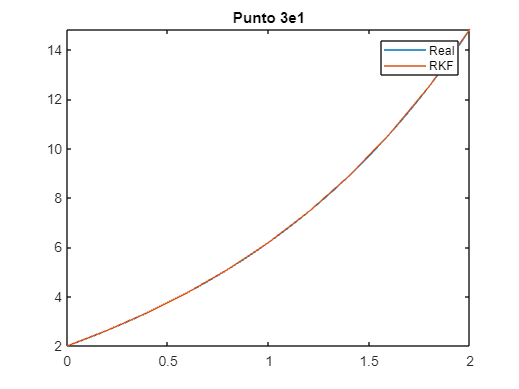

plot(tv3e1,w3e1)
hold off
xlim([0 2])
title('Punto 3e1')
legend('Real', 'RKF')

ii,$y' = 10e^{-\frac{(x-2)^2}{2(0.075)^2}}$

con $0 \leq x \leq4$

h = 0.25

y(0) = 0.5


$$\epsilon = 10^{-5}$$


f3e2(t,y) = 10*exp(-(t-2)^2/(2*0.075^2))

$$f3e2(t, y) = 10\,{\mathrm{e}}^{-\frac{800\,{\left(t-2\right)}^{2}}{9}}$$

real3e2(t) = 3*sqrt(pi)*erf(5*2^(5/2)*t/3-5*2^(7/2)/3)/2^(5/2)+1.439986

$$real3e2(t) = \frac{374176054803257\,\sqrt{2}\,\mathrm{erf}\left(\frac{20\,\sqrt{2}\,t}{3}-\frac{40\,\sqrt{2}}{3}\right)}{562949953421312}+\frac{6485120413018731}{4503599627370496}$$

fplot(real3e2)
hold on
[w3e2, w3e22, tv3e2] = RKF(f3e2, 0, 4, 0.5, 0.0001, 0.25, 10^-5);
w3e2

w3e2 =                        0.5                       0.5                       0.5                       0.5                       0.5                       0.5         0.499999999940668         0.500000035219487         0.500001158018489         0.500024254674424         0.500319262233898         0.502229269867361         0.512450052116756         0.548120577497531         0.604759543187034         0.709435895454736         0.857291738808436          1.07651754535369          1.29688967778161          1.53985416492961          1.75694142520283          1.95815783430945          2.15973812856997          2.27052925234564          2.32740541597638          2.35906720797649          2.37495897672458          2.37921372824826          2.37987534705895           2.3799663776854          2.37997152457567          2.37997156776768          2.37997156776778          2.37997156776778          2.37997156776778          2.37997156776778          2.37997156776778          2.37997156776778


w3e2(end)

ans =           2.37997156776778


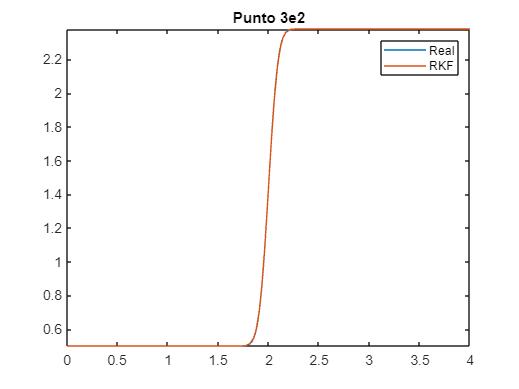

plot(tv3e2,w3e2)
hold off
xlim([0 4])
title('Punto 3e2')
legend('Real', 'RKF')